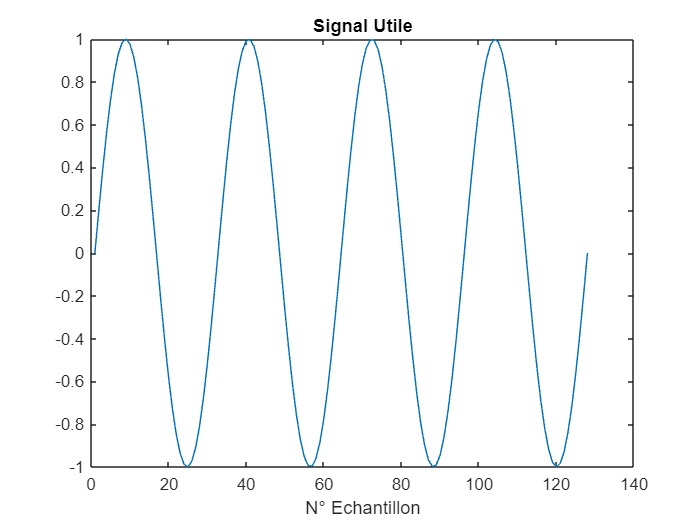

Amplitude = 1;
NbPointSignalUtile = 128;
SignalUtile = GenereSignalUtile(Amplitude, NbPointSignalUtile);

figure;
plot(1:NbPointSignalUtile, SignalUtile);
title('Signal Utile');
xlabel('N° Echantillon');

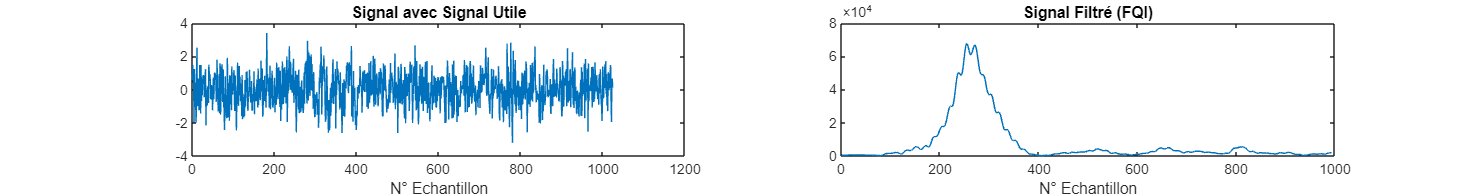

EcartType = 1;
NbPoint = 1024;
present = true;
Signal = GenereSignal(EcartType, NbPoint, Amplitude, NbPointSignalUtile, present);

fig = figure;
fig.Position = [50, 50, 1500, 200];

subplot(1, 2, 1);
plot(1:NbPoint, Signal);
title('Signal avec Signal Utile');
xlabel('N° Echantillon');

SignalFiltre = FQI(Signal, Amplitude, NbPointSignalUtile);

subplot(1, 2, 2);
plot(1:length(SignalFiltre), SignalFiltre);
title('Signal Filtré (FQI)');
xlabel('N° Echantillon');

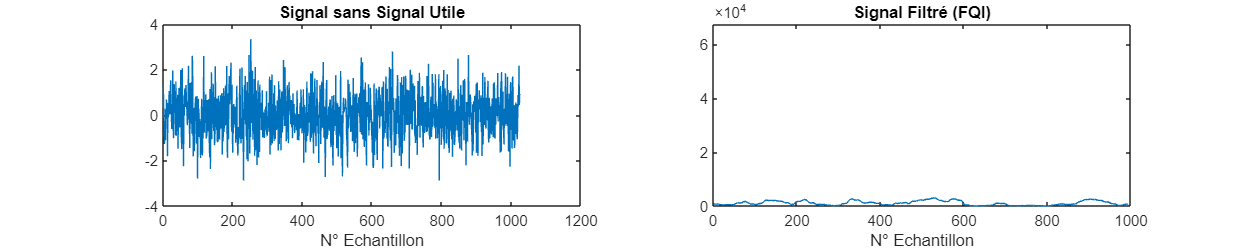

present = false;
SignalSans = GenereSignal(EcartType, NbPoint, Amplitude, NbPointSignalUtile, present);
SignalFiltreSans = FQI(SignalSans, Amplitude, NbPointSignalUtile);

fig = figure;
fig.Position = [50, 50, 1000, 200];

subplot(1, 2, 1);
plot(1:NbPoint, SignalSans);
title('Signal sans Signal Utile');
xlabel('N° Echantillon');

subplot(1, 2, 2);
plot(1:length(SignalFiltreSans), SignalFiltreSans);
title('Signal Filtré (FQI)');
xlabel('N° Echantillon');
ylim([0, max(SignalFiltre)]);

TailleFenetreIntegration = 32;
CoefficientConfiance = 0.95;
Detection = TestHypothese(SignalFiltre, CoefficientConfiance, Amplitude, NbPoint, EcartType, NbPointSignalUtile)

m = 6.7603e+04

moy = 64

threshold = 4.8331e+03

Detection = logical
   1


Detection = TestHypothese(SignalFiltreSans, CoefficientConfiance, Amplitude, NbPoint, EcartType, NbPointSignalUtile)

m = 2.9885e+03

moy = 64

threshold = 4.6013e+03

Detection = logical
   0


NbReals = 100;

TEI = 0;
TEII = 0;

for n = 1:NbReals

    Present = rand() < 0.5;
    Signal = GenereSignal(EcartType, NbPoint, Amplitude, NbPointSignalUtile, Present);
    SignalFiltre = FQI(Signal, Amplitude, NbPointSignalUtile);
    Detection = TestHypothese(SignalFiltre, CoefficientConfiance, Amplitude, NbPoint, EcartType, NbPointSignalUtile);
    
    if Present && ~Detection
        TEI = TEI + 1;
    elseif ~Present && Detection
        TEII = TEII + 1;
    end
end

TEI = TEI / NbReals

TEI = 0

TEII = TEII / NbReals

TEII = 0.4100